# Práctica 1 - Visión por Computador

**Juan Carlos Soriano (1493037) - Jorge Giménez Pérez (1493035)**

### Tarea 1 - Cargar el dataset y dividirlo en dos partes iguales, una para modelar el fondo y otra para detectar

Vamos a usar las imágenes de la carpeta input que van desde la *in001051.jpg* hasta la *in001350.jpg*. Las 150 primeras son para entrenar:

dataset_base_path = '../data/';
images_sizes = [240, 320];

first_image_n = 1050;
last_image_n = 1349;

all_images = zeros(images_sizes(1), images_sizes(2), 300);

for i=first_image_n:last_image_n
    image_path = dataset_base_path + "input/in00" + i + ".jpg";
    all_images(:,:,(i-first_image_n)+1) = rgb2gray(imread(image_path));
end

Mostramos una images cualquiera para ver que todo se ha cargado correctamente en la matriz:

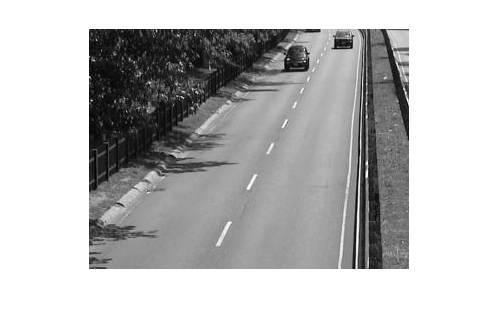

imshow(all_images(:,:,201), [])

Ahora separamos el dataset en test y train:

train_images = all_images(:,:,1:150);
test_images = all_images(:,:,151:300);

### Tarea 2 - Calcular la media y la desviación estándar

Queremos obtener dos matrices. La primera será una que contenga el valor medio de cada pixel de las imágenes de *train* y la segunda será la desviación estándar de cada uno de los píxeles de las imágenes de *train*. Por lo tanto esperamos 2 matrices com medidas 240x320:

training_mean = sum(train_images,3)/150;

Visualizamos que el resultado obtenido tiene sentido:

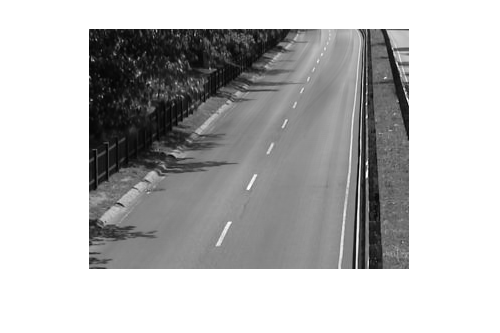

imshow(training_mean, [])


training_std_dev = sqrt(sum(power(train_images -  training_mean, 2), 3)/150);

Visualizamos que el resultado obtenido tiene sentido:

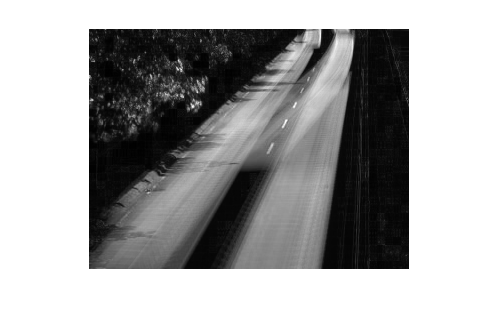

imshow(training_std_dev, [])

### Tarea 3 - Segmentar los coches restando el modelo de fondo

subtracted = test_images - training_mean;
subtracted = subtracted < 0.0001;
subtractedSuperSimpleAux = subtracted;

Comprobamos que el resultado obtenido tiene sentido:

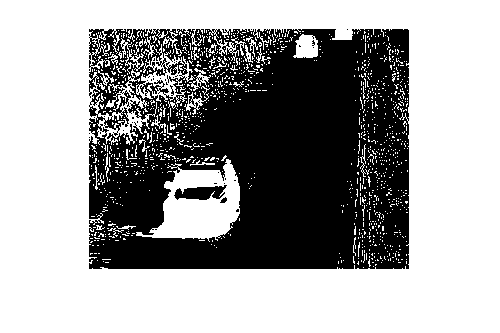

imshow(subtracted(:,:,21), [])

### **Tarea 4 - Segmentar los coches con un modelo más elaborado**

alfa = -0.2;
beta = -20;
subtracted = test_images-training_mean;
subtracted = subtracted < (alfa * training_std_dev +  beta);
subtractedAux = subtracted;

Comprobamos que el resultado obtenido tiene sentido:

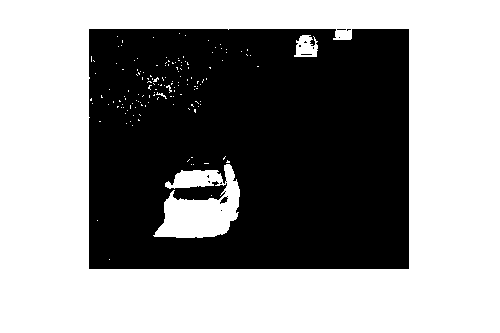

imshow(subtracted(:,:,21), [])

Vemos una mejora substancial donde el ruido causado por el movimiento de las hojas de los árboles se ha eliminado en gran medida minetras que el movimiento de los coches es lo más resaltado.

### Tarea 5 - Grabar un vídeo con los resultados

Usando los resultados obtenidos con las tareas anteriores, generaremos na secuancia de vídeo mostrando todos los frames.

generate_video(subtractedSuperSimpleAux, "super-simple");
generate_video(subtractedAux, "simple");
generate_video(subtractedAux, "erode");
generate_video(subtractedAux, "dilate");
generate_video(subtractedAux, "opening");
generate_video(subtractedAux, "closing");
generate_video(subtractedAux, "custom");

Estos vídeos de salida se pueden visualizar en **../data/**, el nombre de estos sigue el siguiente formato: **matlab_<*****opcion*****>VideoSample.avi**.

### Tarea 6 - Evaluar la bondad de los resultados

Para evaluar cuan bueno es nuestro modelo frente al *groundtruth *dado en el mismo dataset dode encontramos los fotogramas de la cámara de tráfico, utilizaremos métricas como el *accuracy*. Para ello, compararemos fotograma a fotograma los resultados de diferentes configuraciones aplicadas a nuestro programa contra el *groundtruth *antes mencionado.

También acompañaremos al *accuracy *con otras métricas tales como *precision*, *recall* i *f1-score*, que nos ayudarán a tener una mejor perspectiva de la calidad de los resultados obtenidos.

option_set = ["super-simple", "simple", "erode", "dilate", "opening", "closing", "custom"];
ground_truth = zeros(240,320,150);
results = zeros(240,320,150);

for i=1201:1350
    ground_truth(:,:,i-1200) = imread("../data/groundtruth/gt00" + i + ".png");
end
ground_truth = ground_truth > 0;

for option=option_set
    for i=1:150
        results(:,:,i) = imread("../data/videos/matlab_" + string(option) + string(i) + ".png");
        results = results > 0;
    end
    
    subtraction = results - ground_truth;
    good_pixels = sum(subtraction(:)==0);
    all_possible = size(subtraction,1)*size(subtraction,2)*size(subtraction,3);
    accuracy = good_pixels/all_possible;
    disp("Accuracy of option: '" + option + "' -> " + accuracy);
    
end

Accuracy of option: 'super-simple' -> 0.76834
Accuracy of option: 'simple' -> 0.97582
Accuracy of option: 'erode' -> 0.96452
Accuracy of option: 'dilate' -> 0.93959
Accuracy of option: 'opening' -> 0.97603
Accuracy of option: 'closing' -> 0.97299
Accuracy of option: 'custom' -> 0.96853


function generate_video(sequence, option)
v = VideoWriter('../data/matlab_' + option + 'VideoSample.avi', 'Uncompressed AVI');
v.FrameRate = 30;
kernel = strel('square', 5);
open(v);
for k = 1:size(sequence, 3)
    final_frame = sequence(:,:,k);
    if option == "erode"
        final_frame = imerode(final_frame,kernel);
    elseif option == "dilate"
        final_frame = imdilate(final_frame, kernel);
    elseif option == "opening"
        final_frame = imopen(final_frame, kernel);
    elseif option == "closing"
        final_frame = imclose(final_frame, kernel);
    elseif option == "custom"
        final_frame = imerode(final_frame, kernel);
        for i=1:5
            final_frame = imdilate(final_frame, kernel);
        end
    end
    imwrite(final_frame, "../data/videos/matlab_" + option + k + ".png")
    writeVideo(v, mat2gray(final_frame))
end
close(v);
end